#### Segon Parcial 

# Problema 2

La calamarsa es produeix per la pujada i baixada repetida de partícules de gel en el corrent ascendent d'una tempesta. Quan aquestes partícules es fan prou grosses, l'arrossegament aerodinàmic del corrent ascendent ja no pot suportar el pes de la calamarsa, i cau del núvol de tempesta.

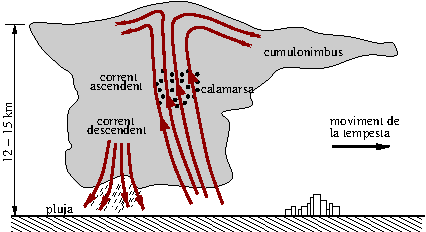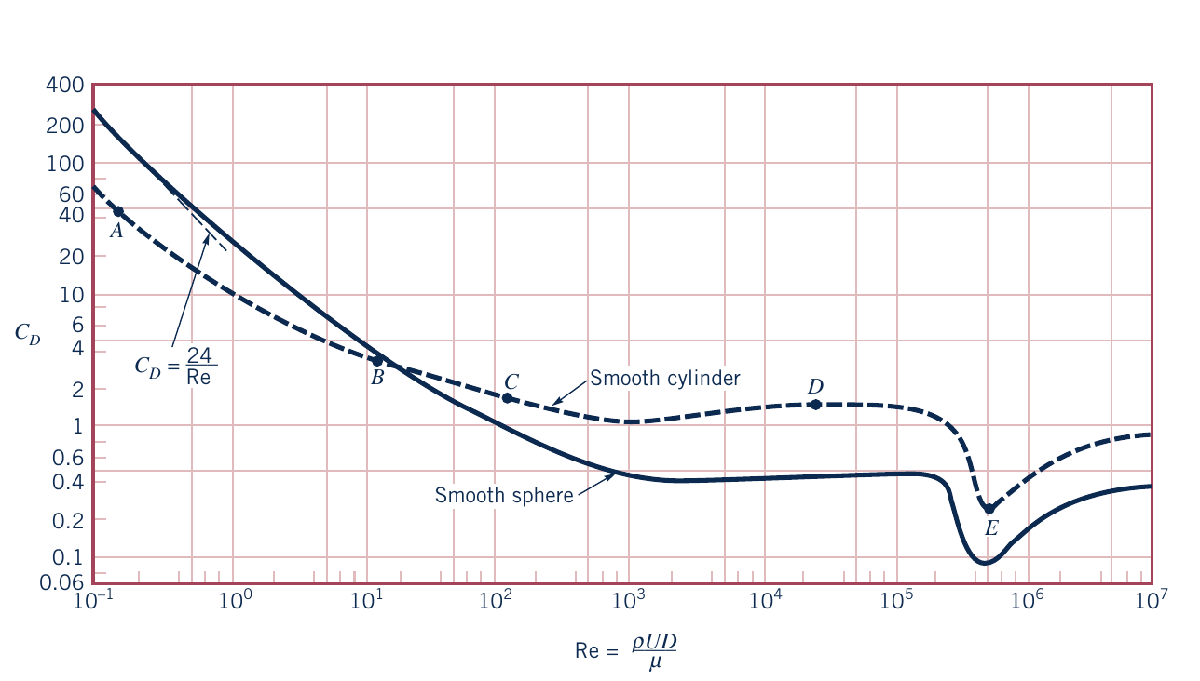

Fes una estimació de la velocitat del corrent ascendent necessari per produir una calamarsa de 4 cm de diàmetre **(2P)**.

rho_calamarsa = 1000; %kg/m³, és gel i prenem la de l'aigua
rho_aire = 1.2;       %kg/m³
D= 0.04;              %m, diàmetre de la calamarsa, suposada esfèrica
V = (4*pi/3)*(D/2)^3;   %m³, el seu volum
A = pi*D^2/4;         %m², àrea frontal
g = 9.81;             %m/s²
viscocin = 1.49e-5;   %m^2/s, és la viscositat cinemàtica de l'aire

La calamarsa pot tenir formes molt variades però sovint s'assemblen prou a una partícula esfèrica, i per això ens donen un diàmetre aproximat de $D=4$cm. En equilibri mecànic, el pes de la calamarsa iguala l'arrossegament del flux ascendent, 


$$\rho_{calamarsa}\, g V = F_D$$
 

$F_D$ es calcula a partir de: 

- el coeficient d'arrossegament $C_D$ que ens dona la gràfica, 

- de l'àrea frontal $A$ de l'objecte exposat al flux, $A= \pi R^2$ (àrea de la secció màxima de l'esfera),

- i de la velocitat $U$ del flux.


$$F_D = C_D \cdot  \frac{1}{2}\rho_{aire}\,U^2 \cdot  A$$



$$\rho_{calamarsa}\, g V = C_D \cdot  \frac{1}{2}\rho_{aire}\,U^2\cdot A$$
  
$$\Rightarrow$$
     
$$U = \sqrt{\frac{\rho_{calamarsa}}{\rho_{aire}}\frac{2g V}{\, C_D(U) A}}$$
 

Aquí el problema és que $C_D$ ve a la gràfica en funció del Re, que depèn de $U$, que és precisament la incògnita i del seu valor no en tenim ni idea. Si $C_D$ fos donat per una fórmula, iteraríem l'equació amb una calculadora, o la pròpia calculadora ens trobaria la solució sense que nosaltres li haguéssim de dir res més. Però no és el cas.

O sigui que ho farem a mà: suposem qualsevol valor de $C_D$, per exemple 1, que correspon a un Re $\simeq 100$, i calculem $U$:

$C_D^{[0]} = 1$ $\longrightarrow$    $U^{[1]} = 20.9$ m/s

fac = sqrt(rho_calamarsa/rho_aire)*sqrt(2*g*V/A);
CD = 1;
U = fac/sqrt(CD) 

U = 20.8806

Hem acabat? No. Perquè a aquesta velocitat, el Re val

Re = U*D/viscocin

Re = 5.6055e+04

I a aquest Re, $C_D$ no val 1 sinó aproximadament 0.5, o sigui que hem d'iterar un cop més,

$C_D^{[1]} = 0.5$  $\longrightarrow$    $U^{[2]} = 29.5$ m/s $\longrightarrow$    Re$^{[2]} = 79000$

CD = 0.5;
U = fac/sqrt(CD) 

U = 29.5296

Re = U*D/viscocin

Re = 7.9274e+04

I a aquest Re, $C_D$ es pot aproximar al mateix valor de 0.5 que acabem d'utilitzar, amb la qual cosa donem $U^{[2]} \simeq$ 30 m/s com a valor correcte de la velocitat del flux ascendent, dintre de les aproximacions realitzades. 

La iteració ordinària $x^{[n+1]}=g(x^{[n]})$convergeix tan depressa perquè, a banda que aquesta funció iteradora compleix la condició necessària i suficient de convergència ($|g'(x)|<1$ dins l'interval de valors de $x$ que ens interessa, que són sempre Re>1), $C_D$ varia molt lentament amb $U$.